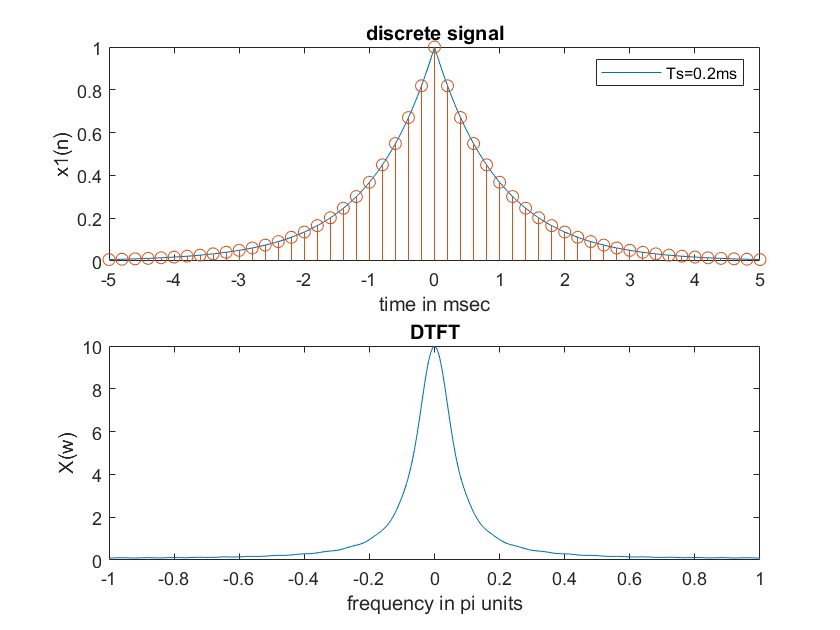

% analog signal
dt=0.00005;
t=-0.005:dt:0.005;
xa=exp(-1000*abs(t));
% discrete signal
fs=5000; % for ex-a
% fs=1000; % for ex-b
ts=1/fs;
n=-25:25;
x=exp(-1000*abs(n*ts));
% discrete time fourier series
K=500;
k=0:K;
w=pi*k/K;
X=x*exp(-1j*n'*w);
X=real(X);
w=[-fliplr(w),w(2:K+1)];
X=[fliplr(X),X(2:K+1)];

% plot
subplot(2,1,1)
plot(t*1000,xa);
title('discrete signal')
xlabel('time in msec')
ylabel('x1(n)');
hold on
stem(n*ts*1000,x);
legend('Ts=0.2ms');
hold off
subplot(2,1,2)
plot(w/pi,X)
title('DTFT')
xlabel('frequency in pi units')
ylabel('X(w)');